# Projekt 5

#### **Zadanie 1**

Dokonaj binaryzacji obrazu *portret.jpg* na dwa sposoby - za pomocą analizy histogramu oraz algorytmem Otsu.

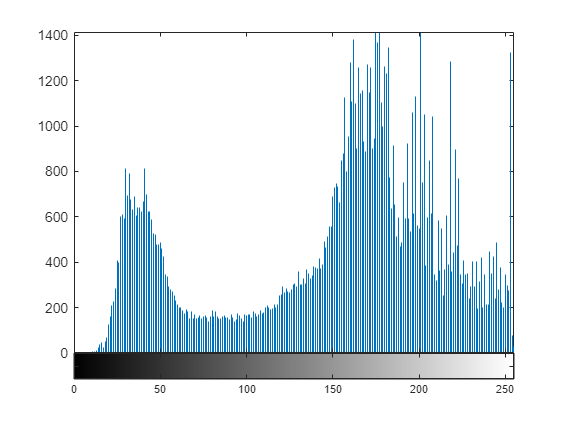

L1=imread('data/portret.jpg');
imhist(L1)

level = graythresh(L1)

level = 0.4706

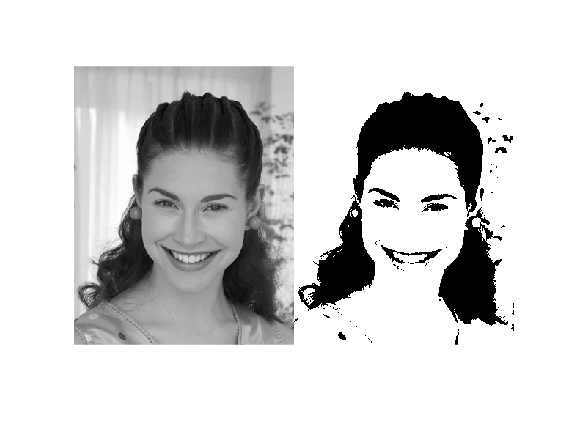

BW = imbinarize(L1,level);
imshowpair(L1,BW,'montage')

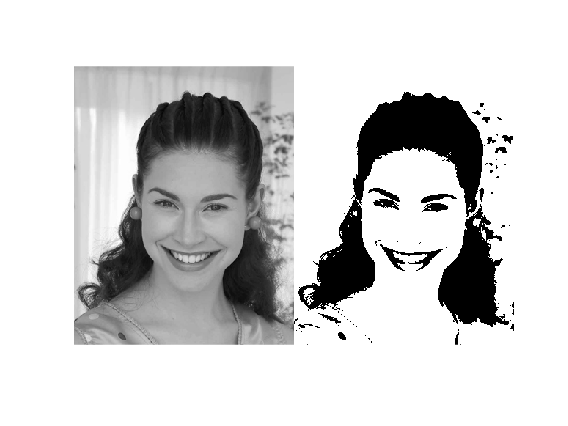

BW_2= im2bw(L1,0.5);
imshowpair(L1,BW_2,'montage')

BW_3 = imbinarize(L1, 0.5);
imshowpair(L1,BW_3,'montage')

*Przydatne funkcje:*

*>*

*graythresh*

*im2bw*

*imbinarize* 

### Zadanie 2

Na podstawie analizy histogramu spróbuj dobrać optymalny próg binaryzacji obrazu *mikolaj.jpg*.

L2 = imread('data/mikolaj.jpg')

L2 = 318×380×3 uint8 array
L2(:,:,1) =

   124   155   149   144   149   150   156   159   160   158   153   153   155   155   152   152   153   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   154   154   156   156   157   156   156   156   156   156   156   156   157   157   156   156   156   154   150   150   154   157   159   157   155   152   153   153   155   155   151   152   153   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   153   153   152   153   153   153   153   155   155   154   155   155   155   153   153   154   154   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   153   153   152   152   152   152   152   152   152   152   152   152   152   152   152   152   152

L3 = im2gray(L2)

L3 = 318×380 uint8 matrix
   179   211   205   203   210   208   205   206   208   208   207   208   208   208   207   207   208   208   208   208   208   208   208   208   208   208   208   208   208   208   208   208   208   208   208   208   208   208   208   208   208   208   208   208   208   208   208   208   209   209
   176   176   210   212   210   207   206   211   209   209   209   209   209   209   208   208   209   209   209   209   209   209   209   209   209   209   209   209   209   209   209   209   209   209   209   209   209   209   209   209   209   209   209   209   209   209   209   209   210   210
   176   186   175   204   207   205   206   207   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   208   208
   177   173   183   177   210   217   210   207   209   209   209   20

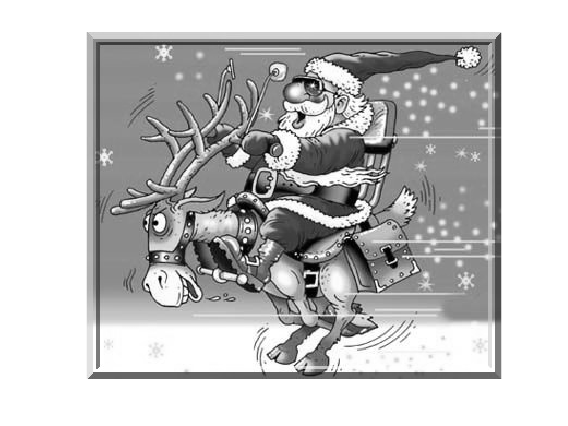

imshow(L3)

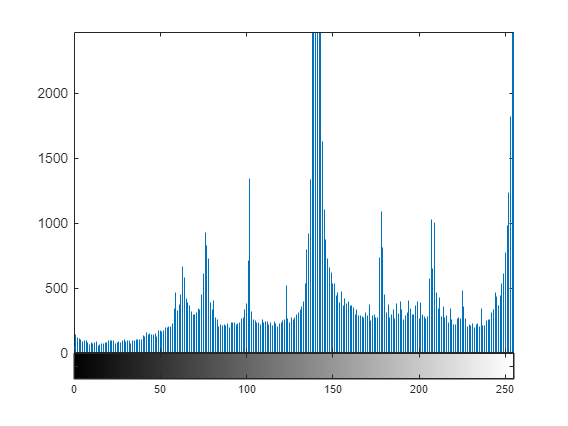

imhist(L3)

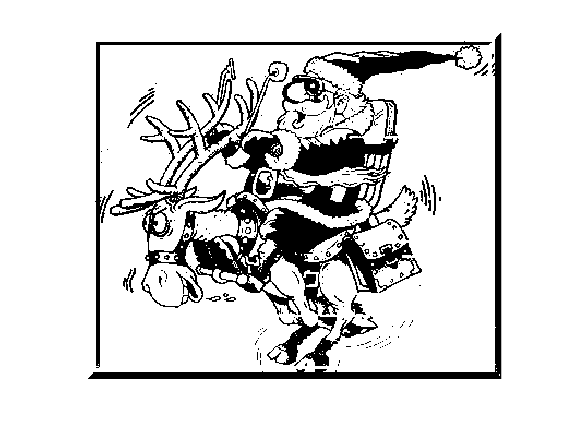

BW_3 = imbinarize(L3, 0.49);
imshow(BW_3)

### Przykład 1

Binaryzacja z dwoma progami. 

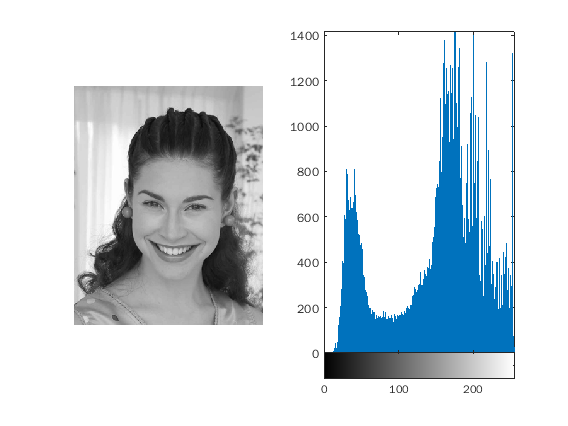

L = imread('data/portret.jpg');
subplot(1,2,1),imshow(L);
subplot(1,2,2),imhist(L);

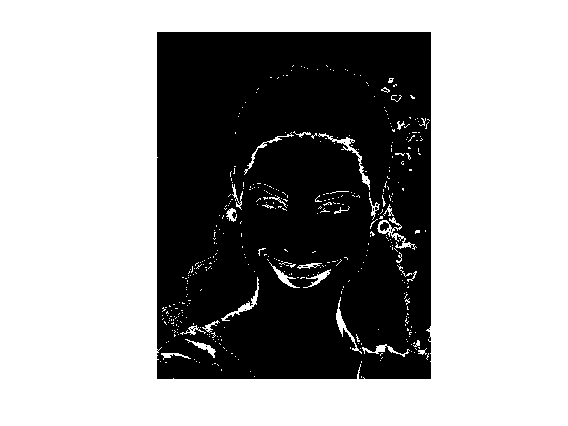

prompt = {'Podaj prog binaryzacji:','Podaj zakres tolerancji'};
odp = inputdlg(prompt);
prog = str2num(odp{1});
tol = str2num(odp{2});
L4 = (L<(prog+tol))&(L>(prog-tol));
figure;
imshow(L4);

*odp = inputdlg(prompt) – zwraca zmienną typu *cell*, w której są przechowywane elementy typu *string

*prog = str2num(odp{1}) – odwołanie do 1 elementu w zmiennej odp i konwersja na typ numeryczny*

### Zadanie 3

Zmodyfikuj powyższy przykład w taki sposób, aby użytkownik klikał na obraz i w ten sposób ustalał próg binaryzacji (wartość będzie pobierana z miejsca kliknięcia), a następnie wprowadzał zakres tolerancji do okna dialogowego. 

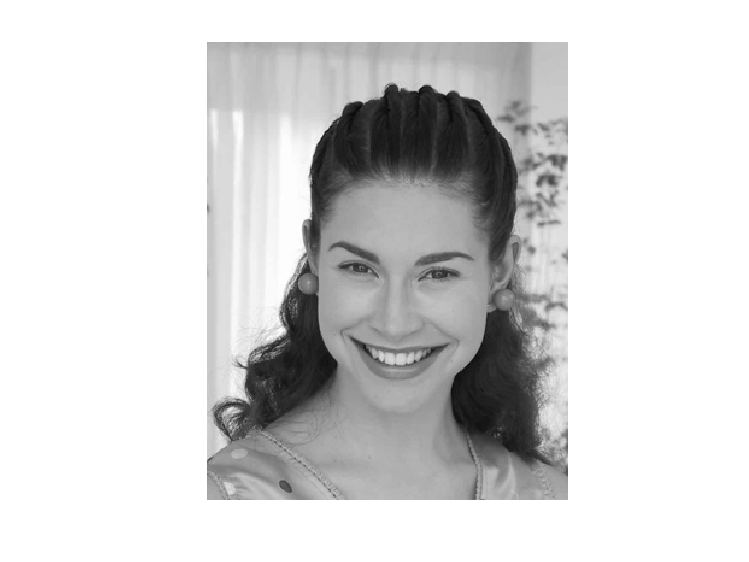

x = 132.2467

y = 117.0721

L4 = imread('data/portret.jpg');
figure; 
imshow(L4);
[x,y] = ginput(1)

prog = L4(round(y),round(x))

prog = uint8
113

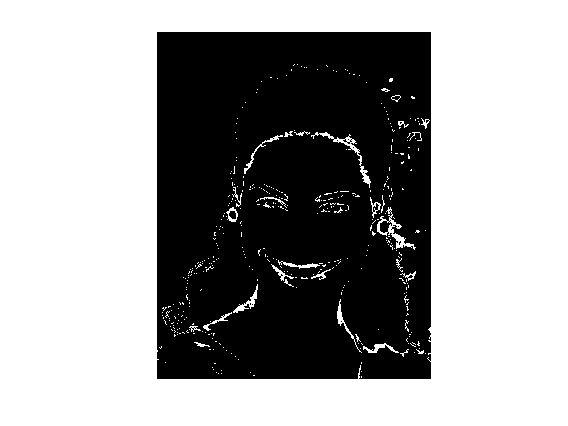


prompt = {'Podaj zakres tolerancji'};
odp = inputdlg(prompt);
tol = str2num(odp{1});


L5 = (L4<(prog+tol))&(L4>(prog-tol));
figure;
imshow(L5);

### Zadanie 4

Za pomocą stworzonego kodu spróbuj tak dobrać parametry binaryzacji na obrazie *cells.bmp*, aby wyróżnić kontury komórek.

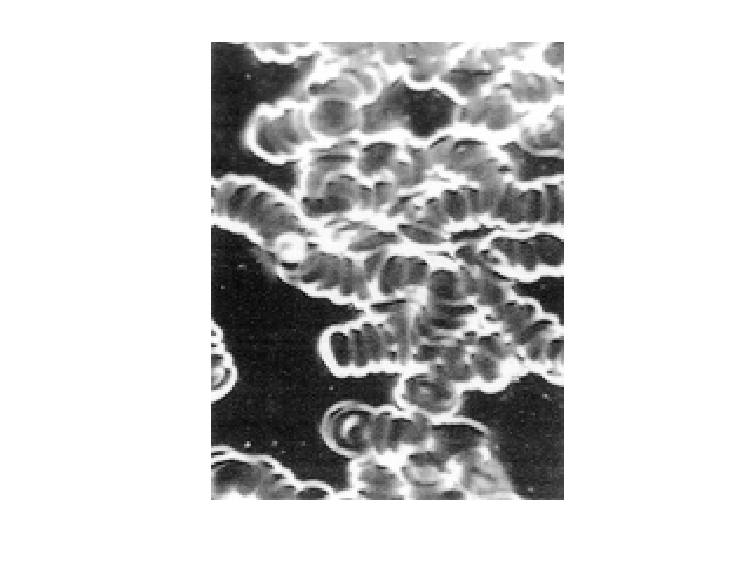

x = 49.5284

y = 131.4225

L6 = imread('data/cells.bmp');
figure; 
imshow(L6);
[x,y] = ginput(1)

prog = L6(round(y),round(x))

prog = uint8
244

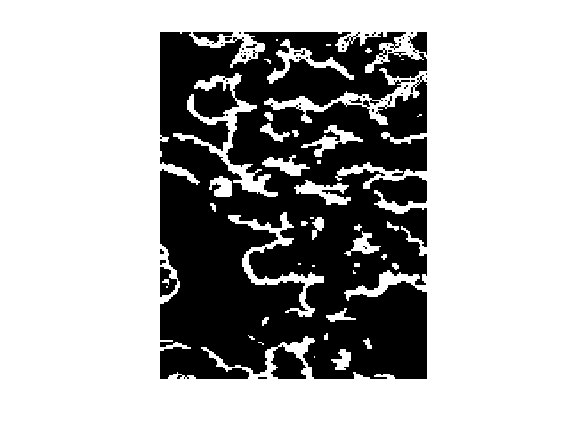


prompt = {'Podaj zakres tolerancji'};
odp = inputdlg(prompt);
tol = str2num(odp{1});


L7 = (L6<(prog+tol))&(L6>(prog-tol));
figure;
imshow(L7);

%prog = ok. 244   tol = ok. 30

### Zadanie 5

Przeprowadź binaryzację obrazu *tekst.png *używając globalnej oraz lokalnej metody wyznaczania progu.

LT = imread('data/tekst.png')

LT = 1150×914×3 uint8 array
LT(:,:,1) =

   138   138   139   139   139   139   140   139   139   139   140   140   141   141   141   142   142   143   143   143   144   144   144   144   144   145   146   147   147   147   147   148   149   149   148   148   149   149   149   149   149   150   151   152   152   152   153   153   154   154   154   154   154   155   155   155   155   155   155   155   155   155   156   158   158   157   157   158   158   159   160   160   161   161   161   160   161   161   162   162   162   162   163   163   164   165   165   165   165   165   165   166   166   166   165   165   165   165   165   166   166   167   167   168   168   169   170   170   171   171   171   171   171   172   173   173   173   173   173   173   173   173   174   175   175   176   177   177   177   177   177   177   178   179   179   180   180   180   180   180   180   180   181   181   182   183   183   182   182   182   183   183   183   183   184   185   186   187   187   18

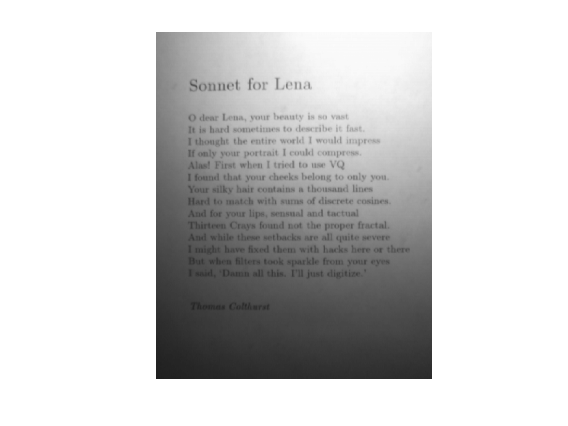

imshow(LT)

LT = im2gray(LT)

LT = 1150×914 uint8 matrix
   138   138   139   139   139   139   140   139   139   139   140   140   141   141   141   142   142   143   143   143   144   144   144   144   144   145   146   147   147   147   147   148   149   149   148   148   149   149   149   149   149   150   151   152   152   152   153   153   154   154
   139   139   139   139   139   139   139   139   139   140   140   141   141   141   142   143   143   143   143   143   143   143   143   143   144   145   146   147   147   147   147   148   149   149   149   149   149   149   149   149   149   150   151   152   153   153   153   153   154   155
   139   139   139   139   139   139   139   139   139   140   140   141   141   141   141   142   142   143   143   143   143   143   143   143   144   144   145   146   147   147   147   148   149   149   149   149   149   149   149   149   149   150   151   152   153   153   153   153   154   154
   139   139   139   139   139   139   139   139   139   140   140   1

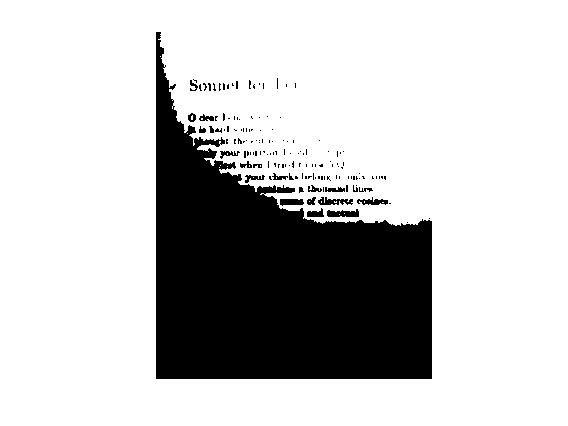

BW_Tg = imbinarize(LT, 'global');
imshow(BW_Tg)

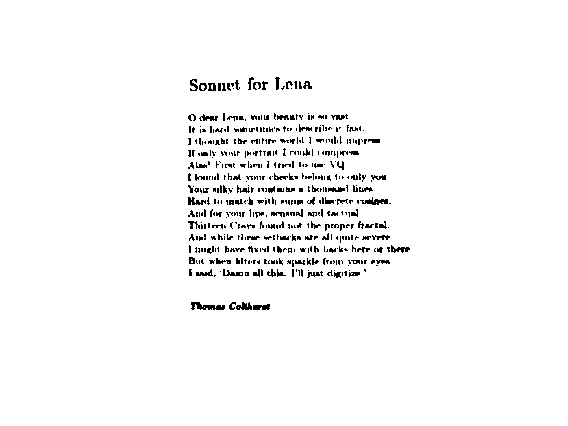

BW_Ta = imbinarize(LT, 'adaptive', 'ForegroundPolarity','dark','Sensitivity',0.5);
imshow(BW_Ta)

### Zadanie 6*

Na bazie zadania 3 stwórz program służący do selekcji kolorów. Użytkownik kliknięciem na obrazie wskaże barwę wzorcową, następnie otworzy się okno, w którym będzie można wprowadzić zakres tolerancji. Zakres ten będzie wybrany z macierzy RGB i przedstawiony w nowym oknie na czarnym tle. Przykłady wykonania:

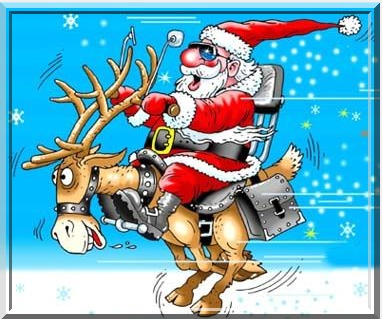                        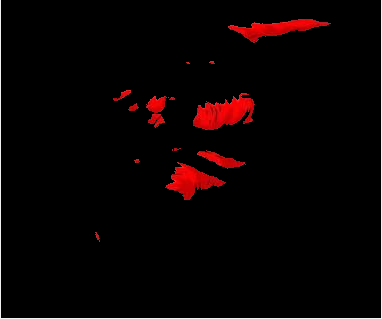



Lm = imread('data/mikolaj.jpg');
Lm

Lm = 318×380×3 uint8 array
Lm(:,:,1) =

   124   155   149   144   149   150   156   159   160   158   153   153   155   155   152   152   153   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   154   154   156   156   157   156   156   156   156   156   156   156   157   157   156   156   156   154   150   150   154   157   159   157   155   152   153   153   155   155   151   152   153   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   153   153   152   153   153   153   153   155   155   154   155   155   155   153   153   154   154   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   153   153   152   152   152   152   152   152   152   152   152   152   152   152   152   152   152

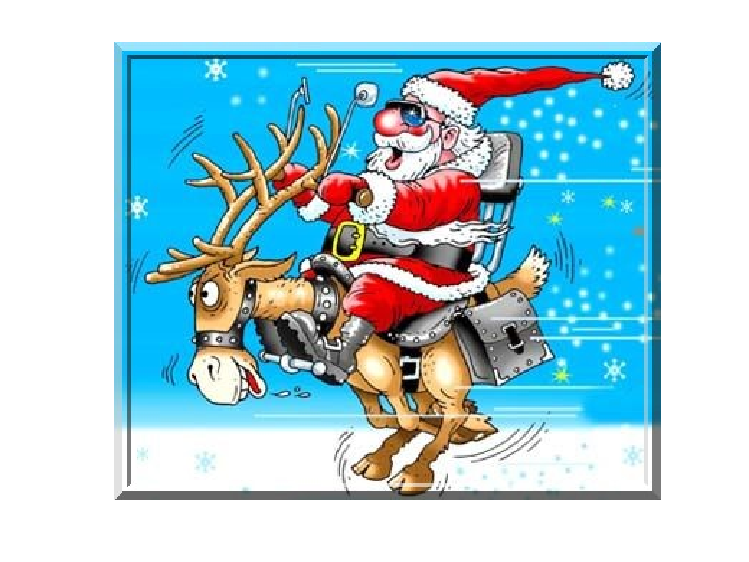

x = 211.3297

y = 117.4934


figure; 
imshow(Lm);
[x,y] = ginput(1)

prog = Lm(round(y),round(x),:)

prog = 1×1×3 uint8 array
prog(:,:,1) =

   240


prog(:,:,2) =

   11


prog(:,:,3) =

   18


prompt = {'Podaj zakres tolerancji'};
odp = inputdlg(prompt);
tol = str2num(odp{1});
LmRR = Lm(:,:,1)

LmRR = 318×380 uint8 matrix
   124   155   149   144   149   150   156   159   160   158   153   153   155   155   152   152   153   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   154   154
   123   121   154   155   151   149   155   164   159   157   153   153   156   156   154   153   154   154   156   154   156   154   156   154   156   154   156   154   156   154   156   154   156   154   156   154   156   154   156   154   156   154   156   154   156   154   156   154   154   154
   124   134   120   148   150   148   151   154   153   151   147   147   151   153   153   151   151   150   151   150   151   150   151   150   151   150   151   150   151   150   151   150   151   150   151   150   151   150   151   150   151   150   151   150   151   150   151   150   149   148
   125   120   128   122   157   164   155   151   156   154   150   

LmGG = Lm(:,:,2)

LmGG = 318×380 uint8 matrix
   198   231   224   223   233   229   220   220   223   224   226   227   227   227   226   226   227   227   227   227   227   227   227   227   227   227   227   227   227   227   227   227   227   227   227   227   227   227   227   227   227   227   227   227   227   227   227   227   228   228
   194   195   229   232   232   228   223   227   225   226   228   229   229   228   227   227   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   228   230   229
   193   203   194   224   228   226   224   224   225   226   227   228   227   226   224   224   225   226   225   226   225   226   225   226   225   226   225   226   225   226   225   226   225   226   225   226   225   226   225   226   225   226   225   226   225   226   225   226   229   230
   194   191   202   197   230   236   230   226   228   229   231   

LmBB = Lm(:,:,3)

LmBB = 318×380 uint8 matrix
   223   255   253   253   255   255   255   255   255   255   255   255   249   251   255   255   255   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   255   255
   222   222   255   255   255   255   255   255   255   255   255   255   248   250   255   255   255   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   253   255   255   255
   224   234   223   250   250   249   255   255   250   249   250   249   241   243   254   255   254   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   252   254   254
   227   221   229   220   249   255   255   255   253   250   252   

progR = prog(:,:,1)

progR = uint8
240

progG = prog(:,:,2)

progG = uint8
11

progB = prog(:,:,3)

progB = uint8
18

LmR = (LmRR<(progR+tol))&(LmRR>(progR-tol));
LmG = (LmGG<(progG+tol))&(LmGG>(progG-tol));
LmB = (LmBB<(progB+tol))&(LmBB>(progB-tol));

Lmm = cat(3, LmR, LmG, LmB)

Lmm = 318×380×3 logical array
Lmm(:,:,1) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

Lm

Lm = 318×380×3 uint8 array
Lm(:,:,1) =

   124   155   149   144   149   150   156   159   160   158   153   153   155   155   152   152   153   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   154   154   156   156   157   156   156   156   156   156   156   156   157   157   156   156   156   154   150   150   154   157   159   157   155   152   153   153   155   155   151   152   153   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   153   153   152   153   153   153   153   155   155   154   155   155   155   153   153   154   154   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   153   153   152   152   152   152   152   152   152   152   152   152   152   152   152   152   152

figure()
imshow(Lmm)

Error using images.internal.imageDisplayValidateParams>validateCData (line 122)
If input is logical (binary), it must be two-dimensional.

Error in images.internal.imageDisplayValidateParams (line 30)
common_args.CData = validateCData(common_args.CData,image_type);

Error in <a href=